# Signal after MAX2771

%rawdata = randi([0 1], [1 50e3]); 
%rawdata = [1 0 1 1 0 0 1 0 0 1 1 0 0 1 1];
rawdata = repmat([1 0 1 0 1 0 0 0 1 1],1,30);

fca     = 1.023e6;          % C/A code frequency
%fc      = 1575.42e6;        % Carrier frequency
fs      = 20*fca;
n       = 1;                % BPSK(1) fc = n*1.023e6; %code rate BPSK(n) 
%                               spreading code rate n*1.023 MHz
codeLength = round(1023/n); 

fdoppler = [1010, 300, -200, -500];
ca_codes = [ 1,  8,  20, 12];
code_phase = [100, 30, 834, 514];

% Rsignal = 2*( ...
%             .25*Received_Simplified(rawdata,fca,fs,fdoppler(1) ...
%             ,ca_codes(1),1,code_phase(1)) + ...
%           ...
%           .25*Received_Simplified(rawdata,fca,fs,fdoppler(2), ...
%           ca_codes(2),1,code_phase(2)) + ...
%           ...
%           .25*Received_Simplified(rawdata,fca,fs,fdoppler(3), ...
%           ca_codes(3),1,code_phase(3)) + ...
%           ...
%           .25*Received_Simplified(rawdata,fca,fs,fdoppler(4), ...
%           ca_codes(4),1,code_phase(4)));

Rsignal = 4*(.25*Received_Simplified(rawdata,fca,fs, ...
               fdoppler(1),ca_codes(1),1,0) + ...
            .25*Received_Simplified(rawdata,fca,fs, ...
               fdoppler(4),ca_codes(4),1,514));

%Rsignal = .5*(Received_Simplified(rawdata,fca,fs, ...
%              fdoppler(1),ca_codes(1),1,code_phase(1)));

[I,Q, clk] = MAX2771_simplified(Rsignal, fs, round(2), false);

## Defining the PLL tracking loop

function out = pd(I,Q)      % Phase Detector
    if I ~= 0
        out = atan(Q./I)/(2*pi);
    else
        out = 0;
    end    
    %out = (atan2(Q,I)) / (2*pi);
    %out = Q/sqrt(I^2 + Q^2);
end

IQ = I + 1i*Q;

block_size = 1*length(IQ)/(20*length(rawdata));

gc = data_mapper(gold_code_L1(codeLength,1));
gc = expand(gc,20*length(rawdata));
gc = upsampler(gc,length(IQ)/length(gc));

omega = zeros(1, length(IQ)/block_size + 1);
omega_init = .97*fdoppler(1);
omega(1) = omega_init;
filt_I = zeros(1, length(IQ)/block_size + 1);
Kp = 10;
Ki = 1;
Kd = 0.5;

IQ_data = zeros(1,length(IQ));
nco_out = zeros(1,length(IQ));
pd_out = zeros(1,length(IQ)/block_size);
phase_ramp = 0;
phase_acc = 0;

delta_omega = zeros(1,length(IQ)/block_size);
local_time_idx = 0:(block_size-1);
%T_PID = block_size/clk;
alpha = 0.;
delta = 100; % Hz por bloco

for i = 1:length(IQ)/block_size
    index = (1:block_size) + (i - 1) * block_size;
    phase_ramp = phase_acc + 2.*pi.*omega(i).*local_time_idx./clk;
    phase_acc = mod(phase_ramp(end) + 2*pi*omega(i)/clk, 2*pi);
    nco_out(index) = exp(-1i.*phase_ramp);
    IQ_data(index) = IQ(index).* ...
        nco_out(index).*gc(index);
    IP(i) = sum(real(IQ_data(index)))/block_size;
    QP(i) = sum(imag(IQ_data(index)))/block_size;

    % FIXED: Store and use the current error immediately at index (i)
    current_error = pd(IP(i), QP(i));
    pd_out(i) = current_error;
    
    % FIXED: Integrator now uses the current_error without a 1-block delay
    if i == 1
        filt_I(i+1) = Ki * current_error;
        filt_D = 0;
    else
        filt_I(i+1) = Ki * current_error + filt_I(i);
        filt_D = Kd * (current_error - pd_out(i-1));
    end    
    
    % FIXED: All terms now use the synchronized current tracking states
    d_omega = Kp * current_error + filt_I(i+1) + filt_D;
    delta_omega(i) = d_omega;
    
    omega(i+1) = omega_init + delta_omega(i);
end

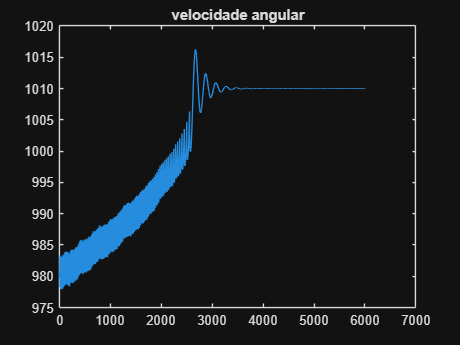

figure; plot(omega)
title('velocidade angular');

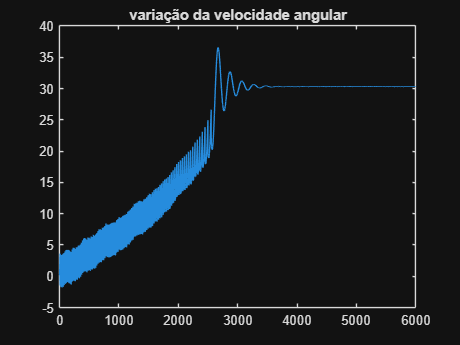

figure; plot(delta_omega)
title('variação da velocidade angular');

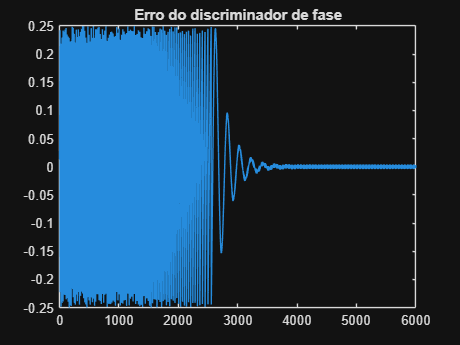

figure; plot(pd_out);
title('Erro do discriminador de fase');

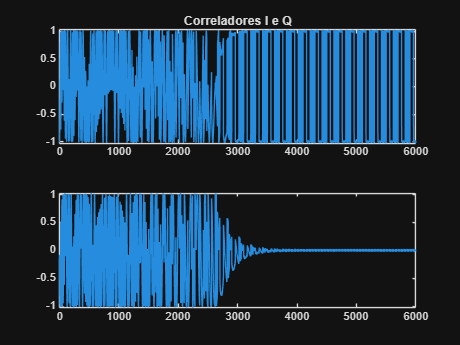

figure; subplot(2,1,1); plot(IP);
title('Correladores I e Q'); subplot(2,1,2); plot(QP);

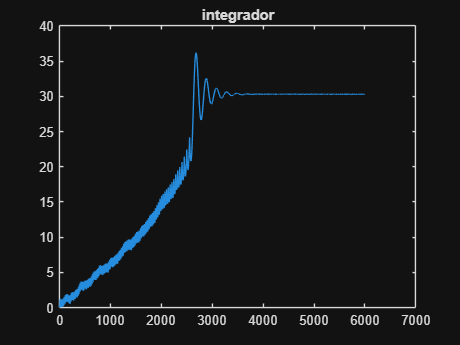

figure; plot(filt_I); title("integrador")

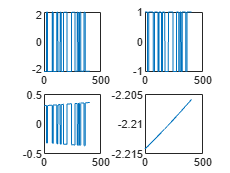

figure;
subplot(2,2,1)
plot(real(IQ(block_size-400:block_size).*exp(-1j*2.*pi.*100.*(block_size-400:block_size)./clk)));
subplot(2,2,3)
plot(imag(IQ(block_size-400:block_size).*exp(-1j*2.*pi.*100.*(block_size-400:block_size)./clk)));
subplot(2,2,2)
plot(gc(block_size-400:block_size));
subplot(2,2,4)
plot(real(IQ(block_size-400:block_size).*exp(-1j*2.*pi.*100.*(block_size-400:block_size)./clk)).*gc(block_size-400:block_size));

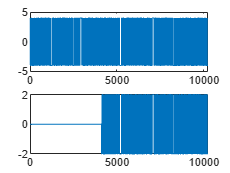

figure;
subplot(2,1,1)
plot(real(IQ(1:block_size)));
subplot(2,1,2)
plot(imag(IQ(1:block_size)));